# Actividad 3: Problema del agente viajero

**Alumno:** Pablo Ruiz Molina

**Fecha: **14.02.2025

% Limpieza de la consola, variables y figuras
clc; clear; close all;

## Introducción

Esta actividad consiste en la implementación de 3 métodos para determinar un camino óptimo para el **Problema del Agente Viajero (PAV)**; en particular para hallar el recorrido óptimo de la figura que se muestra a continuación. Los 3 métodos a implementar serán el método de **Fuerza Bruta**, el método de **Held-Karp** y el algoritmo de **Colonia de Hormigas**.

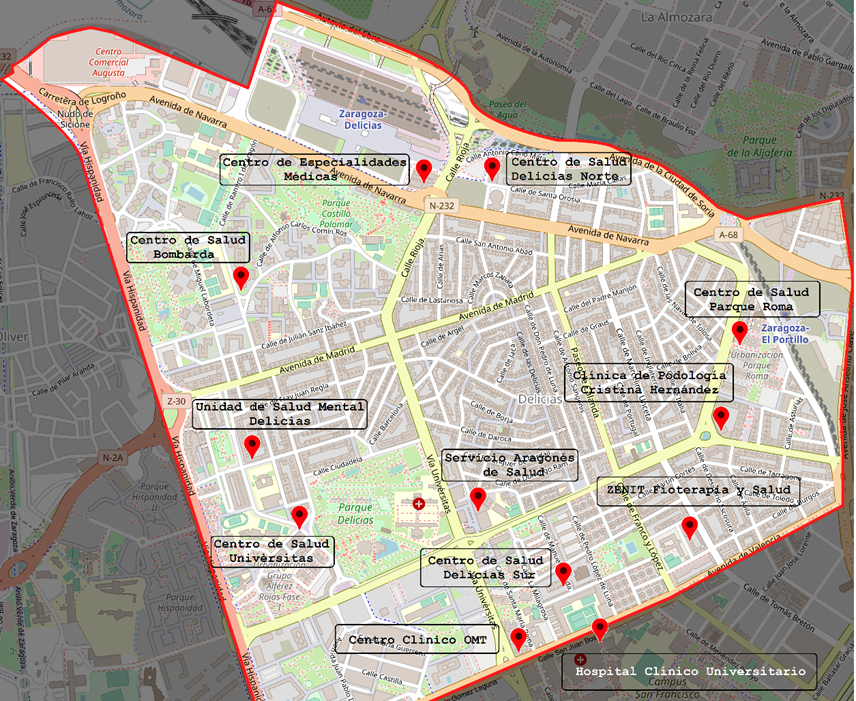

El trabajo se basa en obtener, en primer lugar, **la matriz de adyacencias (tiempos)** que representa los tiempos de desplazamiento entre los centros de distribución, así como la **matriz de adyancencias (distancias)** entre esos puntos. Posteriormente, se aplican los tres métodos sobre esas matrices para determinar el recorrido que **minimice el tiempo de distribución**, considerando además un tiempo fijo de 20 minutos de entrega en cada centro. El hecho que se pida minimizar el tiempo de distribución implica que se en cada método se va a trabajar sobre la matriz de adyacencias (tiempos) de manera exclusiva. La matriz de adyacencias (distancias) se va a usar para calcular la distancia recorrida, una vez tenemos el orden de visita de cada centro.

A lo largo del documento se describen teóricamente de manera somera los fundamentos de cada uno de los métodos y se analizan los resultados obtenidos, comparando la **eficiencia y precisión de cada enfoque**. Notar cómo en cada método se inclue un **grafo sobre el mapa** real resaltando al recorrido realizado por cada uno de los algoritmos. Finalmente, se incluyen las implementaciones de cada método así como algunas funciones clave.

## Extracción de los datos desde el Excel

En primer lugar es necesario cargar los datos relevantes desde el archivo `ingmaco03_act3_anexo.xlsx`. Este archivo contiene información esencial sobre los centros de distribución, las distancias entre ellos (en kilómetros) y los tiempos estimados de recorrido (en minutos). Se implementa la carga de datos en **MATLAB**, manteniendo la estructura de nombres de los centros para facilitar su uso en los cálculos posteriores.

% Nombre del archivo
filename = 'ingmaco03_act3_anexo.xlsx';

% Cargar nombres de los centros desde la primera columna
nombres_centros = readcell(filename, 'Sheet', 'Distancias', 'Range', 'A4:A15');

etiquetas_nodos = arrayfun(@(i) sprintf('%s (%d)', nombres_centros{i}, i), ...
                        1:numel(nombres_centros), 'UniformOutput', false);

% Cargar la matriz de tiempos
matriz_t = readmatrix(filename, 'Sheet', 'Tiempos', 'Range', 'B4:M15');
% Cargar la matriz de distancias
matriz_d = readmatrix(filename, 'Sheet', 'Distancias', 'Range', 'B4:M15');

% Mostrar la matrices de tiempos
disp(array2table(matriz_t, 'VariableNames', nombres_centros, 'RowNames', nombres_centros));

            SAS    CSB    CEM    CSDN    CSPR    CPCH    ZFS    CSDS    HCU    OMT    CSU    USMD
            ___    ___    ___    ____    ____    ____    ___    ____    ___    ___    ___    ____

    SAS     NaN    NaN      7    NaN      10     NaN       5    NaN       8    NaN     11     10 
    CSB     NaN    NaN      5      6     NaN       8       8      9     NaN    NaN    NaN      4 
    CEM       7      5    NaN      2       7       7     NaN      9       9      6    NaN    NaN 
    CSDN    NaN      6      2    

% Mostrar la matrices de distancias
disp(array2table(matriz_d, 'VariableNames', nombres_centros, 'RowNames', nombres_centros));

            SAS     CSB     CEM     CSDN    CSPR    CPCH    ZFS     CSDS    HCU     OMT     CSU     USMD
            ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

    SAS      NaN     NaN    1200     NaN    1200     NaN    1000     NaN     800     NaN     700     900
    CSB      NaN     NaN    1000    1100     NaN    1800    2100    1800     NaN     NaN     NaN     650
    CEM     1200    1000     NaN     230    1300    1400     NaN    1600    1900    1700     NaN     NaN
    CSD

## Transformar a un grafo completo

Para resolver el **Problema del Agente Viajero (PAV)** correctamente, o lo que es lo mismo, para conseguir el circuito Hamiltoniano óptimo, se necesita que el grafo sea completo, es decir, que todos los centros de distribución estén conectados entre sí. Así pues, es necesario detectar los valores `NaN` en la matrices de adyacencias y reemplazarlos con `Inf`. Esto garantizará que los grafos sigan siendo válidos, permitiendo que los algoritmos de resolución del PAV (Fuerza Bruta, Held-Karp, Colonia de Hormigas) nunca elijan caminos inexistentes, pero manteniendo la estructura correcta de los grafos.

% Asegurar que la diagonal principal de las matrices sea cero. No hay lazos
% en los centros.
matriz_d(1:size(matriz_d,1) + 1:end) = 0;
matriz_t(1:size(matriz_t,1) + 1:end) = 0;

% Reemplazar valores NaN por Inf en las matrices
matriz_d(isnan(matriz_d)) = Inf;
matriz_t(isnan(matriz_t)) = Inf;

% Mostrar la matrices de tiempos (diagonal en 0, NaN -> Inf);
disp(array2table(matriz_t, 'VariableNames', nombres_centros, 'RowNames', nombres_centros));

            SAS    CSB    CEM    CSDN    CSPR    CPCH    ZFS    CSDS    HCU    OMT    CSU    USMD
            ___    ___    ___    ____    ____    ____    ___    ____    ___    ___    ___    ____

    SAS       0    Inf      7    Inf      10     Inf       5    Inf       8    Inf     11     10 
    CSB     Inf      0      5      6     Inf       8       8      9     Inf    Inf    Inf      4 
    CEM       7      5      0      2       7       7     Inf      9       9      6    Inf    Inf 
    CSDN    Inf      6      2    

% Mostrar la matrices de distancias (diagonal en 0, NaN -> Inf);
disp(array2table(matriz_d, 'VariableNames', nombres_centros, 'RowNames', nombres_centros));

            SAS     CSB     CEM     CSDN    CSPR    CPCH    ZFS     CSDS    HCU     OMT     CSU     USMD
            ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

    SAS        0     Inf    1200     Inf    1200     Inf    1000     Inf     800     Inf     700     900
    CSB      Inf       0    1000    1100     Inf    1800    2100    1800     Inf     Inf     Inf     650
    CEM     1200    1000       0     230    1300    1400     Inf    1600    1900    1700     Inf     Inf
    CSD

## Mostrar los grafos resultantes

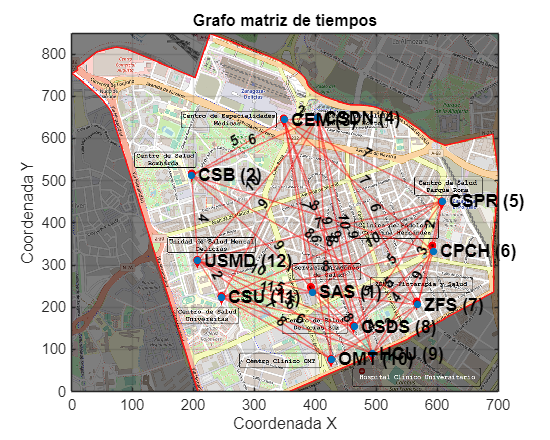

dibujar_grafo_mapa(matriz_t, etiquetas_nodos, filename, [], ...
                   'mapa.png', 'Grafo matriz de tiempos');

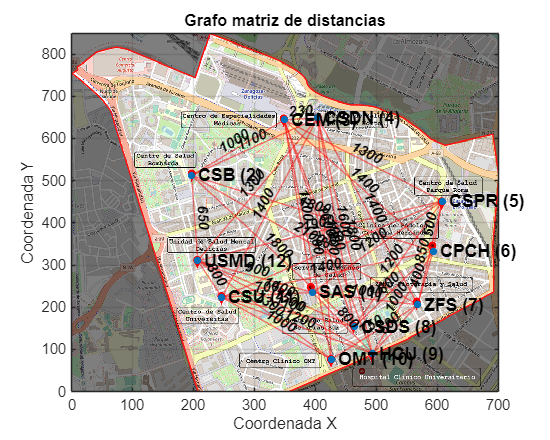

dibujar_grafo_mapa(matriz_d, etiquetas_nodos, filename, [], ...
                   'mapa.png', 'Grafo matriz de distancias');

## Método de Fuerza Bruta

El **Método de Fuerza Bruta** es una técnica exhaustiva para resolver el **Problema del Agente Viajero (PAV)**. Este método evalúa todas las posibles rutas y selecciona la de menor coste, garantizando la solución óptima. Sin embargo, su **complejidad es factorial **`O(n!)`, lo que lo hace computacionalmente costoso a medida que aumenta el número de ciudades.

tic;
[ruta_optima_FB, coste_minimo_FB, distancia_recorrida_FB] = fuerza_bruta(matriz_t, matriz_d);
tiempo_ejecucion_FB = toc;

disp([ ...
    'Tiempo empleado para la ejecución del método de Held-Karp: ', num2str(tiempo_ejecucion_FB),' msec' newline , ...
    'Ruta óptima encontrada con Held-Karp:',newline, strjoin(etiquetas_nodos(ruta_optima_FB), ' -> ' ) newline, ...
    'Tiempo mínimo del recorrido: ', num2str(coste_minimo_FB + 11*20), ' min' newline, ...
    'Distancia total recorrida: ', num2str(distancia_recorrida_FB/1000), ' kms' ...
    ])

Tiempo empleado para la ejecución del método de Held-Karp: 22.3242 msec
Ruta óptima encontrada con Held-Karp:
SAS (1) -> HCU (9) -> CPCH (6) -> CSPR (5) -> CSDS (8) -> CSU (11) -> USMD (12) -> CSB (2) -> CSDN (4) -> CEM (3) -> OMT (10) -> ZFS (7) -> SAS (1)
Tiempo mínimo del recorrido: 274 min
Distancia total recorrida: 10.33 kms


Se observa cómo este método consumo un tiempo de unos 20 segundos y obtiene la silución óptima, que no es más que un tiempo mínimo del recorrido de 274 min y una distancia recorrida de 10.33 kms.

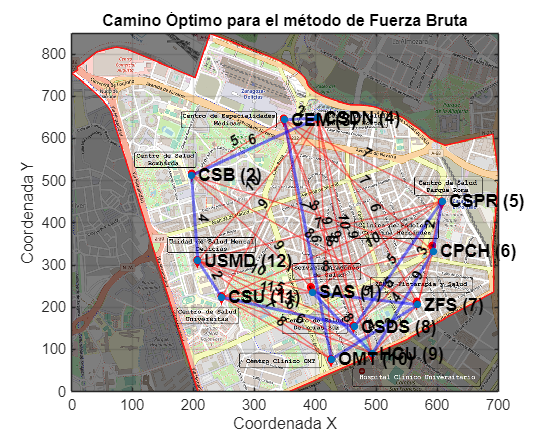

dibujar_grafo_mapa(matriz_t, etiquetas_nodos, filename, ruta_optima_FB, ...
                   'mapa.png', 'Camino Óptimo para el método de Fuerza Bruta');

## Método de Held-Karp

El método **Held-Karp** es un algoritmo basado en programación dinámica que resuelve de manera exacta el Problema del Agente Viajero (PAV). Este problema consiste en encontrar el recorrido con el coste mínimo que permita a un viajero visitar todas las ciudades exactamente una vez y regresar a la ciudad de origen. El método Held-Karp optimiza la solución mediante el almacenamiento de resultados intermedios en una estructura de datos eficiente, reduciendo la complejidad computacional en comparación con la fuerza bruta. Mientras que una búsqueda exhaustiva tiene una complejidad factorial O(n!), **Held-Karp la reduce a O(n² * 2ⁿ)**, lo que lo hace factible para un número moderado de ciudades (**hasta **`n ≈ 20`).

% Ejecutar el método Held-Karp usando la matriz de tiempos
tic;
[ruta_optima_HK, coste_minimo_HK, distancia_recorrida_HK] = held_karp(matriz_t, matriz_d);
tiempo_ejecucion_HK = toc;

disp([ ...
    'Tiempo empleado para la ejecución del método de Held-Karp: ', num2str(tiempo_ejecucion_HK),' msec' newline , ...
    'Ruta óptima encontrada con Held-Karp:',newline, strjoin(etiquetas_nodos(ruta_optima_HK), ' -> ' ) newline, ...
    'Tiempo mínimo del recorrido: ', num2str(coste_minimo_HK + 11*20), ' min' newline, ...
    'Distancia total recorrida: ', num2str(distancia_recorrida_HK/1000), ' kms' ...
    ])

Tiempo empleado para la ejecución del método de Held-Karp: 0.091553 msec
Ruta óptima encontrada con Held-Karp:
SAS (1) -> ZFS (7) -> OMT (10) -> CEM (3) -> CSDN (4) -> CSB (2) -> USMD (12) -> CSU (11) -> CSDS (8) -> CSPR (5) -> CPCH (6) -> HCU (9) -> SAS (1)
Tiempo mínimo del recorrido: 274 min
Distancia total recorrida: 10.33 kms


Este segundo método consume un tiempo de unos 100 milisegundos y consigue también la solución óptima. Es muy interesante la reducción del tiempo de ejecución con respecto al de Fuerza Bruta.

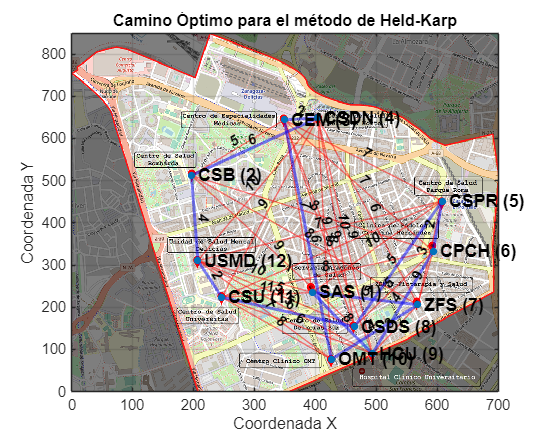

dibujar_grafo_mapa(matriz_t, etiquetas_nodos, filename, ruta_optima_HK, ...
                   'mapa.png', 'Camino Óptimo para el método de Held-Karp');

## Método de Colonia de Hormigas

El **Algoritmo de Colonia de Hormigas (ACO - Ant Colony Optimization)** es un método heurístico inspirado en el comportamiento de las hormigas en la búsqueda de caminos óptimos. Este método es ideal para optimizar el Problema del Agente Viajero (PAV) cuando `n` es grande (`n > 12`), ya que encuentra soluciones cercanas al óptimo sin necesidad de explorar todas las rutas posibles.

num_hormigas = 20;
iteraciones = 100;
alpha = 1; % Peso de feromonas
beta = 2; % Peso de distancia
rho = 0.5; % Tasa de evaporación
Q = 100; % Cantidad de feromonas depositadas

tic;
[ruta_optima_ACO, coste_minimo_ACO, distancia_recorrida_ACO] = aco(matriz_t, matriz_d, num_hormigas, iteraciones, alpha, beta, rho, Q);
tiempo_ejecucion_ACO = toc;

disp([ ...
    'Tiempo empleado para la ejecución del método de Held-Karp: ', num2str(tiempo_ejecucion_ACO),' msec' newline , ...
    'Ruta óptima encontrada con Held-Karp:',newline, strjoin(etiquetas_nodos(ruta_optima_ACO), ' -> ' ) newline, ...
    'Tiempo mínimo del recorrido: ', num2str(coste_minimo_ACO + 11*20), ' min' newline, ...
    'Distancia total recorrida: ', num2str(distancia_recorrida_ACO/1000), ' kms' ...
    ])

Tiempo empleado para la ejecución del método de Held-Karp: 0.04566 msec
Ruta óptima encontrada con Held-Karp:
SAS (1) -> HCU (9) -> ZFS (7) -> OMT (10) -> CEM (3) -> CSDN (4) -> CSB (2) -> USMD (12) -> CSU (11) -> CSDS (8) -> CPCH (6) -> CSPR (5) -> SAS (1)
Tiempo mínimo del recorrido: 278 min
Distancia total recorrida: 9.73 kms


Notar cómo en este caso el tiempo mínimo recorrido es de 4' más que en las soluciones exactas. Interesante también resaltar que la distancia recorrida ahora es de en torno a medio km menos que en las soluciones exactas. No obstante, esto es circunstancial, en el sentido de que lo que se ha minimizado es el tiempo empleado en el recorrido, y no la distancia.

Otra última cosa a comentar de este algoritmo es que se ha fijado la semilla para obtener un resultado fijo a la hora de ejecutar este código. Si se deja la generación de números aleatorios sin fijar, se puede notar cómo el resultado varia e incluso hay veces que se he encuentra la solución exacta. Eso sí, nunca se obtiene una solución mejor que la solución exacta, cómo era de esperar.

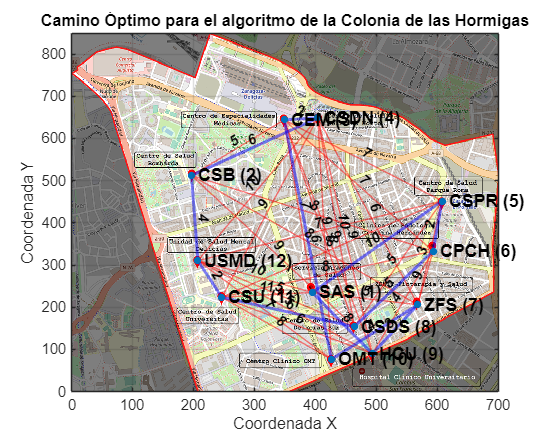

dibujar_grafo_mapa(matriz_t, etiquetas_nodos, filename, ruta_optima_ACO, ...
                   'mapa.png', 'Camino Óptimo para el algoritmo de la Colonia de las Hormigas');

## Evaluación de resultados y comparación entre métodos

Tras la implementación de los tres métodos para la resolución del Problema del Agente Viajero (PAV), se han obtenido los resultados que se detallan a continuación, considerando tanto la calidad de la solución (tiempo y distancia del recorrido) como el tiempo de ejecución de cada algoritmo.

resultados_comparacion = table(...
    {'Fuerza Bruta'; 'Held-Karp'; 'ACO'}, ...
    [coste_minimo_FB + 11*20; coste_minimo_HK + 11*20; coste_minimo_ACO + 11*20], ...
    [distancia_recorrida_FB/1000; distancia_recorrida_HK/1000; distancia_recorrida_ACO/1000], ...
    [tiempo_ejecucion_FB; tiempo_ejecucion_HK; tiempo_ejecucion_ACO], ...
    'VariableNames', {'Metodo', 'TiempoRecorrido_min', 'Distancia_km', 'TiempoEjecucion_s'});

disp(resultados_comparacion);

         Metodo         TiempoRecorrido_min    Distancia_km    TiempoEjecucion_s
    ________________    ___________________    ____________    _________________

    {'Fuerza Bruta'}            274               10.33              22.324     
    {'Held-Karp'   }            274               10.33            0.091553     
    {'ACO'         }            278                9.73             0.04566     



En primer lugar, el método de Fuerza Bruta arrojó el resultado óptimo, ya que, por su naturaleza, este método evalúa absolutamente todas las combinaciones posibles de rutas entre los centros de distribución. Como era de esperar, esta exhaustividad garantiza la obtención de la mejor solución posible. Sin embargo, esta precisión tiene un alto coste computacional, dado que el número de permutaciones crece factorialmente con el número de nodos. En este caso, con 12 centros, el tiempo de ejecución fue considerablemente elevado, alcanzando aproximadamente 20 segundos. Esta circunstancia evidencia que el método de Fuerza Bruta solo resulta viable en problemas de muy pequeña escala, siendo impracticable en situaciones con un mayor número de ciudades.

Por otro lado, el método de Held-Karp, basado en programación dinámica, también encontró la solución óptima, coincidiendo con la obtenida mediante Fuerza Bruta. Sin embargo, este método mostró una notable mejora en términos de eficiencia computacional, ya que logró la solución en apenas 100 milisegundos. Esto se debe a que el algoritmo Held-Karp reduce drásticamente el número de combinaciones evaluadas, aprovechando la redundancia de subproblemas en la construcción del circuito hamiltoniano. Como resultado, Held-Karp se perfila como la opción más eficiente para problemas de tamaño moderado, como el caso de los 12 centros evaluados.

Finalmente, el algoritmo de Colonia de Hormigas (ACO) proporcionó una solución cercana al óptimo, con una ligera desviación tanto en el tiempo del recorrido como en la distancia total, respecto a los métodos exactos. Esta variación es propia de los algoritmos heurísticos, que buscan soluciones aproximadas, explorando el espacio de búsqueda a partir de la colaboración e interacción entre agentes. A pesar de no garantizar la optimalidad, ACO se ejecutó en aproximadamente la mitad de tiempo que el de Held-Karp, mostrando un equilibrio adecuado entre precisión y rapidez. Su principal ventaja radica en su escalabilidad, ya que su rendimiento relativo mejora frente a métodos exactos conforme aumenta el número de nodos, siendo especialmente útil para problemas de mayor dimensión.

## Anexo: Funciones Necesarias

#### Método de Fuerza Bruta

function [ruta_optima, coste_minimo, distancia_recorrida] = fuerza_bruta(dmatrix, matriz_d)
    numCiudades = size(dmatrix, 1); % Número de ciudades
    
    % Generar todas las permutaciones posibles de las ciudades (excepto la 1)
    rutas = perms(2:numCiudades);
   
    numRutas = size(rutas, 1); % Número total de rutas posibles
    coste_minimo = inf; % Inicializar el costo mínimo
    ruta_optima = []; % Inicializar la mejor ruta
    
    % Evaluar todas las rutas posibles
    for i = 1:numRutas
        ruta_actual = [1, rutas(i, :), 1]; % Agregar ciudad de origen y regreso
        coste_actual = 0;
        
        % Calcular el coste de la ruta actual
        for j = 1:numCiudades
            coste_actual = coste_actual + dmatrix(ruta_actual(j), ruta_actual(j+1));
        end
        
        % Verificar si la ruta actual es la mejor encontrada
        if coste_actual < coste_minimo
            coste_minimo = coste_actual;
            ruta_optima = ruta_actual;
        end
    end

    distancia_recorrida = calcular_costes(matriz_d, ruta_optima);
    
end

#### Método de Held Karp

function [ruta_optima, coste_minimo, distancia_recorrida] = held_karp(dmatrix, matriz_d)

    % Se establece el número de ciudades totales.
    numCiudades = size(dmatrix(:,1),1);

    % Crea una lista de los primeros n números primos. Cada conjunto de ciudades (S) 
    % se identificará con el producto de sus números primos correspondientes. 
    % Esto permite indexar rápidamente los subconjuntos de ciudades sin necesidad 
    % de usar vectores binarios.
    % Por ejemplo S={3,4,6}, cojerá el producto del tercer, cuarto y sexto primo 
    % (i.e. 5*7*13) como índice del conjunto S.

    num = 50; % Un valor inicial grande para asegurar que hay al menos 12 primos
    numPrim = primes(num); % Generamos los primos hasta num
    while length(numPrim) < numCiudades
        num = num * 2; % Duplicamos el límite si no hay suficientes primos
        numPrim = primes(num);
    end
    numPrim = numPrim(1:numCiudades); % Extraemos solo los primeros 12 primos

    maxConj = prod(numPrim); % El conjunto más grande de todos

    % Se crean e inicializan matrices dispersas para almacenar cada conjunto (sparse para 
    % ahorrar memoria: muchos datos no se usarán).
    
    % d(S, j) → Coste mínimo de visitar las ciudades del conjunto S terminando en j
    d = sparse(maxConj, numCiudades);
    % predecesor(S, j) → Última ciudad visitada antes de llegar a j.
    predecesor = sparse(maxConj, numCiudades);
    
    % Caso base: k = 0. Si S = {ciudad c}, el costo de visitar solo c desde la ciudad 1 es
    % simplemente dmatrix(c,1)
    for c = 2:numCiudades
        d(numPrim(c), c) = dmatrix(c, 1);
    end

    % Caso general
    % 1. Recorremos todos los conjuntos S de s elementos
    for s = 2:numCiudades
        % Para cada tamaño de subconjunto (s ciudades), se generan todas las combinaciones 
        % posibles S de s ciudades restantes usando nchoosek()
        restantes = 2:numCiudades;
        S = nchoosek(restantes, s); % devuelve combinaciones de s elementos de restantes
   
        % 2. Calculamos el coste para cada ciudad k en S
        for ind = 1:size(S(:,1),1) % número de combinaciones posibles    
            for k = 1:s
                % Se analiza cada subconjunto S y cada ciudad k como destino final dentro de S.
                minval = inf;
                
                % 3. Buscar la mejor ciudad m para llegar a k
                sconj = S(ind, :); % subconjunto actual S
                sMenosk = S(ind, :); % subconjunto sin k
                sMenosk(k) = [];
                indc = indexConj(sMenosk, numPrim); % índice único del conjunto S-{k}
    
                % Para cada m en S (excepto k), se busca el mínimo de los posibles caminos que 
                % acaban en k y tienen m como penúltima ciudad.
                % C(S,k) = min{C(S−{k}, m) + D(m, k)}
                for m = 1:s
                    if m == k
                        continue
                    end
                    % al costo calculado de ir de 1 hasta m siguiendo los elementos del conjunto 
                    % (valor almacenado en d(indc, sconj(m))) le sumamos el valor de ir de m a k.
                    dm = dmatrix(sconj(k), sconj(m)) + d(indc, sconj(m));
                    if(dm < minval)
                        minval = dm;
                        indmin = m;
                    end
                end
        
                % 4. Almacenar resultados. Se guarda:
                % d(S, k) → El coste mínimo encontrado.
                % predecesor(S, k) → La penúltima ciudad visitada antes de k.
                indcM = indexConj(S(ind, :), numPrim);
                d(indcM, sconj(k)) = minval;
                predecesor(indcM, sconj(k)) = sconj(indmin);
            end
        end
    end
    
    % 6. Cierre del Circuito (Volver a la Ciudad 1)
    % Se calcula el coste final regresando a la ciudad 1:
    % C(todas las ciudades, j) + D(j, 1)
    coste_minimo = inf;
    for k = 2:numCiudades
        sconj = 2:numCiudades;
        indc = indexConj(sconj, numPrim);
        dm = dmatrix(k, 1) + d(indc, k);
        if(dm < coste_minimo)
            coste_minimo = dm; 
            indmin = k;
        end
    end
    
    % 7. Reconstrucción de la Ruta
    % Se inicializa la ruta con la ciudad 1.
    ruta_optima(numCiudades + 1) = 0;
    ruta_optima(1) = 1;
    
    % Se crea una lista de ciudades no visitadas.
    % 1 -> no visitada
    % 0 -> visitada
    novisitadas = ones([1, numCiudades]);
    novisitadas = logical(novisitadas);
    novisitadas(1) = 0;
    

    identidad = 1:numCiudades;
    for i= 2:numCiudades
            % Se extrae la siguiente ciudad en la ruta (indmin).
            ruta_optima(i) = indmin;
            
            % Miramos el conjunto de ciudades no visitadas
            conjS = identidad(novisitadas);
            
            % Se marca como visitada.
            novisitadas(indmin) = 0;
    
            % Se consulta la ciudad previa con predecesor()
            % Devuelve el penúltimo elemento del camino, esto es, la siguiente ciudad que visitiaremos.
            indS = indexConj(conjS, numPrim);
            indmin = predecesor(indS, indmin);
    end
    
    % Se cierra el circuito.
    ruta_optima(end) = 1;

    distancia_recorrida = calcular_costes(matriz_d, ruta_optima);
  
    % indexConj calcula el índice del conjunto Conj.
    % Emplea numPrim para no recalcularlo
    function indc = indexConj(Conj, numPrim)
        indc = prod(numPrim(Conj));
    end

end

#### Algoritmo de la Colonia de las Hormigas

Incluye la propia función ("*aco*") para ejecutar el algoritmo, la función "*construir_ruta*", la función "*calcular_probabilidades*" y la función "*seleccionar_ciudad*".

function [ruta_optima, coste_minimo, distancia_recorrida] = aco(matriz_t, matriz_d, num_hormigas, iteraciones, alpha, beta, rho, Q)
    rng(2); % Fijar semilla para obtener siempre el mismo resultado

    numCiudades = size(matriz_t, 1); % Número de ciudades
    feromonas = ones(numCiudades) * 1e-6; % Inicializar matriz de feromonas con un valor bajo
    
    ruta_optima = [];
    coste_minimo = inf;
    
    % Ejecutar el algoritmo por un número de iteraciones
    for it = 1:iteraciones
        rutas = zeros(num_hormigas, numCiudades + 1); % Almacena rutas de hormigas
        tiempos = zeros(num_hormigas, 1); % Almacena los tiempos de cada ruta
        
        % Para cada hormiga, construir una solución
        for h = 1:num_hormigas
            ruta_actual = construir_ruta(matriz_t, feromonas, alpha, beta);
            rutas(h, :) = ruta_actual;
            tiempos(h) = calcular_costes(matriz_t, ruta_actual);
            
            % Si encontramos una mejor ruta, la almacenamos
            if tiempos(h) < coste_minimo
                coste_minimo = tiempos(h);
                ruta_optima = ruta_actual;
            end
        end
        
        % Actualizar feromonas
        feromonas = (1 - rho) * feromonas; % Evaporación
        for h = 1:num_hormigas
            for j = 1:numCiudades
                a = rutas(h, j);
                b = rutas(h, j+1);
                feromonas(a, b) = feromonas(a, b) + Q / tiempos(h);
                feromonas(b, a) = feromonas(b, a) + Q / tiempos(h); % Grafo no dirigido
            end
        end
    end

    distancia_recorrida = calcular_costes(matriz_d, ruta_optima);
  
end

%% Función para construir una ruta usando la regla de transición de ACO
function ruta = construir_ruta(matriz_t, feromonas, alpha, beta)
    numCiudades = size(matriz_t, 1);
    ruta = zeros(1, numCiudades + 1);
    ciudad_actual = 1;
    ruta(1) = ciudad_actual;
    
    visitadas = false(1, numCiudades);
    visitadas(1) = true;
    
    for i = 2:numCiudades
        probabilidades = calcular_probabilidades(matriz_t, feromonas, ciudad_actual, visitadas, alpha, beta);
        ciudad_siguiente = seleccionar_ciudad(probabilidades, visitadas);
        ruta(i) = ciudad_siguiente;
        visitadas(ciudad_siguiente) = true;
        ciudad_actual = ciudad_siguiente;
    end
    
    ruta(end) = 1; % Regresar a la ciudad de inicio
end


%% Función para calcular las probabilidades de transición
function probabilidades = calcular_probabilidades(matriz_t, feromonas, ciudad_actual, visitadas, alpha, beta)
    numCiudades = size(matriz_t, 1);
    probabilidades = zeros(1, numCiudades);
    
    for j = 1:numCiudades
        if ~visitadas(j) && j ~= ciudad_actual
            tau = feromonas(ciudad_actual, j)^alpha;
            eta = (1 / matriz_t(ciudad_actual, j))^beta;
            probabilidades(j) = tau * eta;
        end
    end
    
    suma_probabilidades = sum(probabilidades);
    if suma_probabilidades > 0
        probabilidades = probabilidades / suma_probabilidades; % Normalizar
    end
end


%% Función para seleccionar la siguiente ciudad con probabilidad y evitar repeticiones
function ciudad_siguiente = seleccionar_ciudad(probabilidades, visitadas)
    ciudades_disponibles = find(~visitadas); % Ciudades que aún no han sido visitadas
    r = rand;
    acumulado = 0;
    for j = ciudades_disponibles
        acumulado = acumulado + probabilidades(j);
        if r <= acumulado
            ciudad_siguiente = j;
            return;
        end
    end

    ciudad_siguiente = ciudades_disponibles(randi(length(ciudades_disponibles))); % Último recurso

end

#### Función para calcular el coste total de una "ruta" en una matriz de adyacencia.

%% Función para calcular la suma total de costes en  una ruta
function coste_total = calcular_costes(matriz, ruta)
    coste_total = sum(arrayfun(@(j) matriz(ruta(j), ruta(j+1)), 1:length(ruta)-1));
end

#### Función para dibujar grafo en el mapa

function dibujar_grafo_mapa(matriz, etiquetas_nodos, excel_filename, ruta_optima, mapa_filename, titulo_grafo)
    % Definir parámetros para la escala y desplazamiento.
    factor_x = 66;
    factor_y = 98;
    offset_x = 395;
    offset_y = 235;    

    % Obtener tamaño de pantalla para centrar
    scrsz = get(groot, 'ScreenSize'); 
    ancho_figura = 500;
    alto_figura = 400;
    pos_x = (scrsz(3) - ancho_figura) / 2;
    pos_y = (scrsz(4) - alto_figura) / 2;

    % Crear figura centrada y grande
    figure('Position', [pos_x, pos_y, ancho_figura, alto_figura]);
    
    % Mostrar imagen ajustándola a los límites reales
    mapa = flip(imread(mapa_filename)); % Cargar y voltear imagen
    imagesc([0, 700], [0, 850], mapa);
    hold on; % Permite dibujar sobre la imagen
    set(gca, 'YDir', 'normal'); % Corrige orientación del eje Y
    xlim([0 700]);
    ylim([0 850]);

    % Crear el grafo
    G = graph(matriz, etiquetas_nodos, 'upper');

    % Identificar aristas con pesos Inf y eliminar esas aristas del grafo
    G = rmedge(G, find(isinf(G.Edges.Weight)));

    % Crear etiquetas personalizadas para las aristas (sin inf)
    etiquetas = string(G.Edges.Weight);

    % Cargar las coordenadas desde el Excel
    coordenadas = readmatrix(excel_filename, 'Sheet', 'Coordenadas', 'Range', 'F4:G15'); 

    % Ajustar coordenadas con escala y desplazamiento
    X = coordenadas(:, 1) * factor_x + offset_x;
    Y = coordenadas(:, 2) * factor_y + offset_y;

    % Dibujar el grafo con coordenadas ajustadas
    p = plot(G, 'XData', X, 'YData', Y, ...
        'NodeLabel', etiquetas_nodos, 'EdgeLabel', etiquetas);

    % Ajustes visuales del grafo
    p.EdgeColor = [1 0 0]; % Rojo
    p.EdgeFontWeight = 'bold';
    p.EdgeFontSize = 10;
    p.NodeFontWeight = 'bold';
    p.NodeFontSize = 12;

    % Destacar la ruta óptima si está definida
    if ~isempty(ruta_optima)
        highlight(p, ruta_optima, 'EdgeColor', 'b', 'LineWidth', 2);
    end

    % Configuración final del gráfico
    title(titulo_grafo);
    xlabel('Coordenada X');
    ylabel('Coordenada Y');
    grid on;
end